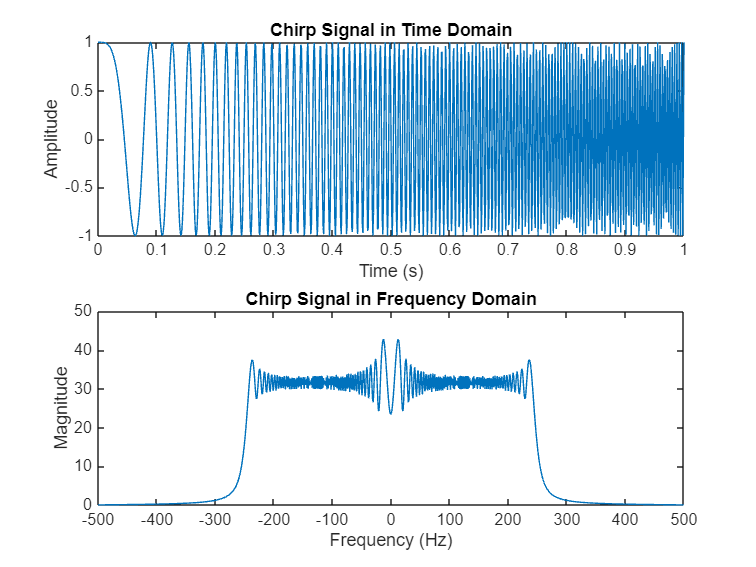

% Define parameters
fs = 1000;                % Sampling frequency in Hz
t = 0:1/fs:1;             % Time vector (1 second duration)
f0 = 0;                   % Start frequency of the chirp
f1 = 250;                 % End frequency of the chirp

% Generate the chirp signal
chirpSignal = chirp(t, f0, t(end), f1);

% Plot the chirp signal in time domain
figure;
subplot(2,1,1);
plot(t, chirpSignal);
title('Chirp Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the chirp signal in frequency domain
subplot(2,1,2);
nfft = length(chirpSignal);
f = (-nfft/2:nfft/2-1) * (fs/nfft);
chirpSignalFFT = fftshift(fft(chirpSignal, nfft));
plot(f, abs(chirpSignalFFT));
title('Chirp Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

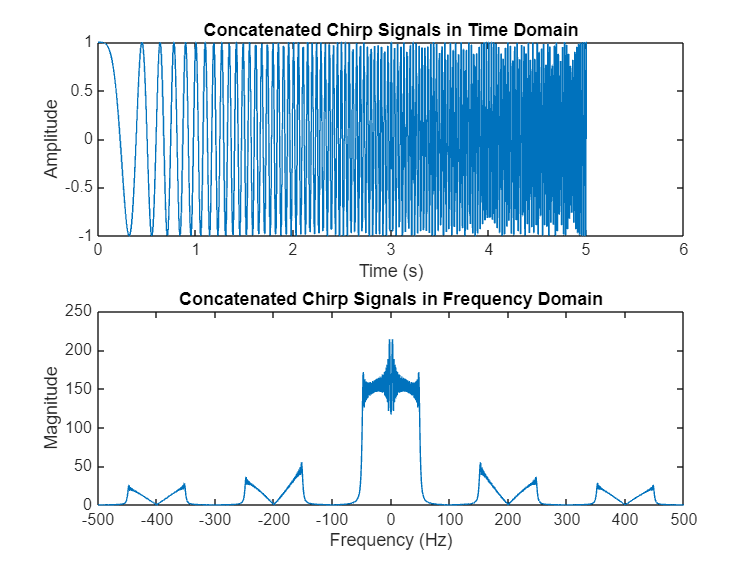


%..............................................................




% Define parameters
fs = 1000;               % Sampling frequency in Hz
duration = 1;            % Duration of each chirp signal in seconds
t = 0:1/fs:duration;     % Time vector for each chirp signal
f0 = 0;                  % Start frequency of the chirp
f1 = 250;                % End frequency of the chirp
numSignals = 5;          % Number of chirp signals

% Initialize matrix to store chirp signals
chirpMatrix = zeros(numSignals, length(t));

% Generate multiple chirp signals and store in matrix
for i = 1:numSignals
    chirpMatrix(i, :) = chirp(t, f0, t(end), f1);
end

% Concatenate all chirp signals into a single vector
chirpVector = chirpMatrix(:)';

% Plot the concatenated chirp signals in time domain
figure;
subplot(2,1,1);
plot((0:length(chirpVector)-1)/fs, chirpVector);
title('Concatenated Chirp Signals in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the concatenated chirp signals in frequency domain
subplot(2,1,2);
nfft = length(chirpVector);
f = (-nfft/2:nfft/2-1) * (fs/nfft);
chirpVectorFFT = fftshift(fft(chirpVector, nfft));
plot(f, abs(chirpVectorFFT));
title('Concatenated Chirp Signals in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

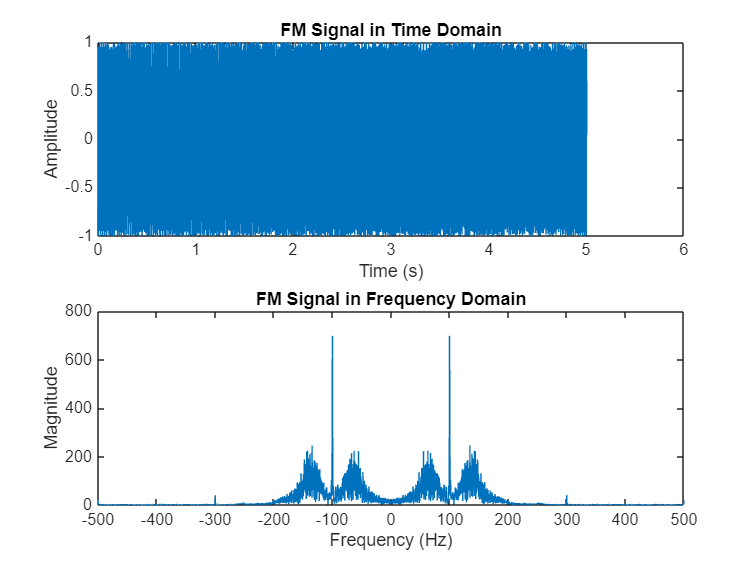

% Define parameters
fs = 1000;               % Sampling frequency in Hz
duration = 1;            % Duration of each chirp signal in seconds
t = 0:1/fs:duration;     % Time vector for each chirp signal
f0 = 0;                  % Start frequency of the chirp
f1 = 250;                % End frequency of the chirp
numSignals = 5;          % Number of chirp signals
carrierFreq = 100;       % Carrier frequency in Hz
freqDeviation = 50;      % Frequency deviation for FM
A = 1;                   % Amplitude of the FM signal

% Initialize matrix to store chirp signals
chirpMatrix = zeros(numSignals, length(t));

% Generate multiple chirp signals and store in matrix
for i = 1:numSignals
    chirpMatrix(i, :) = chirp(t, f0, t(end), f1);
end

% Concatenate all chirp signals into a single vector
chirpVector = chirpMatrix(:)';

% Integrate the baseband (chirp) signal
integratedChirp = cumsum(chirpVector) / fs;

% Generate the FM signal
fmSignal = A * cos(2 * pi * carrierFreq * (0:length(chirpVector)-1) / fs + 2 * pi * freqDeviation * integratedChirp);

% Plot the FM signal in time domain
figure;
subplot(2,1,1);
plot((0:length(fmSignal)-1)/fs, fmSignal);
title('FM Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the FM signal in frequency domain
subplot(2,1,2);
nfft = length(fmSignal);
f = (-nfft/2:nfft/2-1) * (fs/nfft);
fmSignalFFT = fftshift(fft(fmSignal, nfft));
plot(f, abs(fmSignalFFT));
title('FM Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');